# Creating and Training a CNN for Classification

In the "Creating and Training a CNN for Classification" video, you saw how to build, train, and evaluate a simple CNN to classify images of fasteners.

In this reading, you will see additional steps for investigating your data and network.

## Preparing Your Data for Classification

First, create a datastore from the fasteners training data in the course files (the "MathWorks Created\Fasteners\Classification\Train" folder):

filename = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Train";
imdsFasteners = imageDatastore(filename,"IncludeSubfolders",true,"LabelSource","foldernames")

imdsFasteners =   ImageDatastore with properties:

                       Files: {
                              ' ...\Fasteners\Classification\Train\Bolt5_16inx1-1_4in\fastener0001.jpg';
                              ' ...\Fasteners\Classification\Train\Bolt5_16inx1-1_4in\fastener0002.jpg';
                              ' ...\Fasteners\Classification\Train\Bolt5_16inx1-1_4in\fastener0003.jpg'
                               ... and 974 more
                              }
                     Folders: {
                              ' ...\Data\MathWorks Created\Fasteners\Classification\Train'
                              }
                      Labels: [Bolt5_16inx1-1_4in; Bolt5_16inx1-1_4in; Bolt5_16inx1-1_4in ... and 974 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         Defa

### Investigating Your Data

It's essential to understand your data before training. 

Investigating the datastore can tell you important information, such as the number of images in your training dataset:

numImgs = length(imdsFasteners.Files)

numImgs = 977

And the number of images per class using the `countEachLabel` function:

countEachLabel(imdsFasteners)

ans = 19×2 table
           Label            Count
    ____________________    _____

    Bolt5_16inx1-1_4in       51  
    Bolt5_16inx1in           44  
    Bolt5_16inx3_4in         42  
    FinishNail1-1_4in        51  
    FinishNail2in            51  
    HexNut1_4in              52  
    HexNut1_4inThin          52  
    HexNut5_16in             59  
    LockSplitWasher1_4in     52  
    LockSplitWasher3_8in     51  
    RoofingNail1-1_4in       51  
    Screw#10x3_4inPan        53  
    Screw#6x1inFlat          51  
    Screw#8x1-1_2inFlat      54  
    Screw#8x1_2Pan           54  
    Screw#8x3_4inFlat        53  


Run the following code a few times to see a sampling of images and their image size:

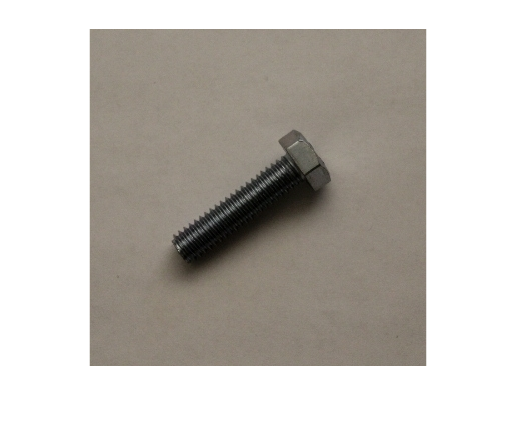

img = read(imdsFasteners);
imshow(img)

size(img)

ans =    337   337     3


You can also read specific images from a datastore using `readimage:`

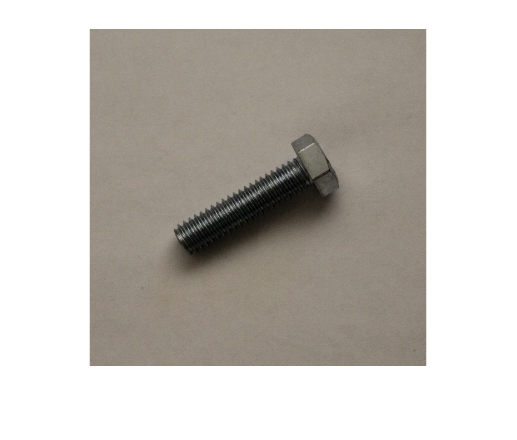

img = readimage(imdsFasteners,45);
imshow(img)

### Creating Training and Validation Sets

As you saw in "Preparing Your Data for Classification," creating a randomized validation set is crucial to avoid overfitting your model to your training data. We saw above that `imdsFasteners` has sufficient images of each class to ensure that setting aside 20% of the training images for validation would create a reasonably-sized validation set.

`splitEachLabel` creates two new image datastores, one for training and one for validation:

[imdsTrain,imdsValidation] = splitEachLabel(imdsFasteners,0.8,"randomized");

## Building Your Network Layers

In the video, you saw how to create a simple CNN in the Deep Network Designer App and export the code to the workspace. The exported code, autogenerated by the app, appears below:

layers = [
    imageInputLayer([227 227 3],"Name","imageinput")
    convolution2dLayer([3 3],32,"Name","conv","Padding","same")
    reluLayer("Name","relu")
    maxPooling2dLayer([5 5],"Name","maxpool","Padding","same")
    fullyConnectedLayer(19,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];

### Exploring Network Layers

Exporting and looking at each layer may not be practical for larger and more complex networks. Fortunately, you can access individual layers and see useful details using dot notation:

% Image input layer
layers(1).Name

ans = 'imageinput'

layers(1).InputSize

ans =    227   227     3


In classification, no matter how large the network, the fully-connected layer will be third from the last layer:

% Fully-connected layer
layers(end-2).Name

ans = 'fc'

layers(end-2).OutputSize    % Number of classes

ans = 19

## Resizing Your Training Data

The following code resizes the training data to meet the expected input size specified in the image input layer:

augTrain = augmentedImageDatastore([227,227],imdsTrain);
augVal = augmentedImageDatastore([227,227],imdsValidation);

## Setting Your Training Options

Here, we leave most options as the default. However, we'll discuss how to choose model options and when to update them to improve your model later in this course.

opts = trainingOptions("adam","ValidationData",augVal,"Shuffle",...
    "every-epoch","Plots","training-progress");

## Training Your Network

This may take some time (about 25 minutes on my CPU).

Checking the box below will train a new classification model for the fasteners dataset. Otherwise, the following code will load the network we trained in the "Creating and Training a CNN for Classification" video, available in the course files. 

% Check the box to train a new network. Otherwise, load the trained network
% from the course files
trainNew = false;
if trainNew
    net = trainNetwork(augTrain,layers,opts);
else
    load fastenerSimpleCNNClassifier.mat
end

### Investigating Your Trained Model

Similar to the above, you can use dot notation to access the layers of your trained network. Use the slider to see different activations for a given image.

net.Layers(2).Weights   % In this model, the second layer is the convolutional layer

ans = 3×3×3×32 single array
ans(:,:,1,1) =

   -0.0623    0.0087   -0.0038
   -0.0116   -0.1232    0.1195
    0.0895   -0.0542    0.0203


ans(:,:,2,1) =

    0.0472   -0.0571    0.0413
    0.0226   -0.1483    0.0971
   -0.0294    0.0433    0.0183


ans(:,:,3,1) =

    0.0574   -0.0018    0.0609
   -0.0438   -0.0424    0.0591
   -0.1367   -0.0437    0.0206


ans(:,:,1,2) =

   -0.1475    0.0323   -0.0451
    0.0461    0.0806    0.0442
   -0.0389   -0.0838   -0.0981


ans(:,:,2,2) =

    0.0205    0.0678    0.0067
    0.0459    0.0843   -0.1229
    0.0423    0.0858   -0.1096


ans(:,:,3,2) =

    0.0472   -0.0386    0.1052
   -0.0990    0.0270    0.0177
    0.0666    0.0989   -0.0575


ans(:,:,1,3) =

   -0.0504    0.0529   -0.0978
   -0.0571   -0.1269   -0.0389
    0.1168   -0.0364    0.0333


ans(:,:,2,3) =

   -0.0802    0.0740    0.0180
    0.0438    0.1261    0.0215
   -0.1255    0.0450   -0.0098


ans(:,:,3,3) =

   -0.0481   -0.0351    0.0415
    0.1203   -0.0732    0.0637
   -0.


act1 = activations(net,img,net.Layers(2,1).Name);

Error using SeriesNetwork/activations (line 932)
The spatial dimension sizes [32 32 3] of the input images to layer 'imageinput' must be greater than or equal to the corresponding minimum input dimension sizes of the layer [227 227 3].

imshow(act1(:,:,1)) % There are 32 filters in this particular convolutional layer

## Evaluating Your Network

Use your trained network to classify your test set. Then, compare these predictions to the actual test labels to determine the model's test accuracy.

filenameTest = "E:\Semester Pendek\MATLAB\Deep Learning for Computer Vision\Data\MathWorks Created\Fasteners\Classification\Test";
imdsTest = imageDatastore(filenameTest,"IncludeSubfolders",true,"LabelSource","foldernames");

Error using imageDatastore (line 139)
Files must be a non-empty character vector or string scalar.


augTest = augmentedImageDatastore([227,227],imdsTest);
testPreds = classify(net,augTest);

testAccuracy = nnz(testPreds == imdsTest.Labels)/length(testPreds)

Investigate how many images of each label were correctly and incorrectly classified using a confusion chart:

confusionchart(imdsTest.Labels,testPreds)

*Copyright 2024 The MathWorks, Inc.*